# Curves in w dimension

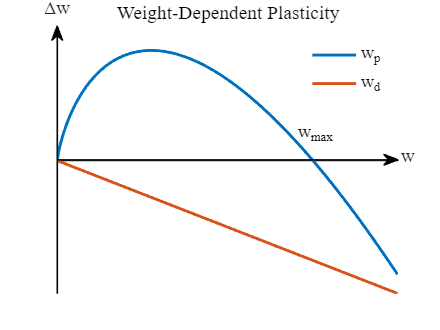

clc; clear;
w = 0.001:0.01:4;
t = 0.001:0.01:100;


w_max = 3;
tau = 20;
c_p = 0.015;
c_d = 0.005;

w_p = c_p*w.*log(w_max./w);
w_d = -c_d*w;

figure('Color', 'w', 'Position', [100, 100, 400, 300]); hold on;
lw = 2;
plot(w, w_p, DisplayName='w_p', LineWidth=lw)
plot(w, w_d, DisplayName='w_d', LineWidth=lw)

text(w_max-0.2, 0.004, "w_{max}", ...
     'FontName', 'Times New Roman', 'FontSize', 12);
legend('Box','off', 'FontName', 'Times New Roman', 'FontSize', 12);
xlabel("w", 'Position', [4.2, -0.001, 0]);
ylabel("\Deltaw", 'Position', [-0., 0.021, -1], 'Rotation', 0);
title("Weight-Dependent Plasticity", ...
      'FontSize', 12, 'FontWeight', 'normal', 'FontName', 'Times New Roman');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ax = gca;
fig = gcf;

% Axis limits
xL = xlim(ax);   % [x_min x_max]
yL = ylim(ax);   % [y_min y_max]

% Axis position in normalized units
ax_pos = get(ax, 'Position');  % [left bottom width height]

% Compute (0,0) in normalized figure coordinates
x0_norm = ax_pos(1) + (0 - xL(1)) / diff(xL) * ax_pos(3);
y0_norm = ax_pos(2) + (0 - yL(1)) / diff(yL) * ax_pos(4);

% Arrow for x-axis: from left to right at y = 0
annotation('arrow', [x0_norm, ax_pos(1) + ax_pos(3)], [y0_norm, y0_norm], 'LineWidth', 0.5);

% Arrow for y-axis: from bottom to top at x = 0
annotation('arrow', [x0_norm, x0_norm], [ax_pos(2), ax_pos(2) + ax_pos(4)], 'LineWidth', 0.5);

set(gca, 'xtick', [], 'ytick', [], 'box', 'off')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'XAxisLocation', 'origin')
print("Figures\SkematicPlasticityCurve.png", '-dpng', '-r300')
exportgraphics(gcf, 'Figures/SkematicPlasticityCurve.pdf', 'ContentType', 'vector', 'BackgroundColor','none', 'Resolution', 300);

# Heatmap in w-t space

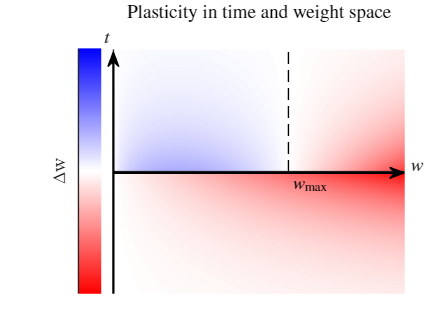


clc; clear;
w = 0.001:0.01:5;
t = -50:0.01:50;

w_max = 3;
tau = 20;
c_p = 0.015;
c_d = 0.010;

[W, T] = meshgrid(w, t);  % T: rows = time, W: columns = weight

% Time-dependent plasticity
Wp = c_p * W .* log(w_max ./ W) .* exp(-T / tau);  % potentiation
Wd = -c_d * W .* exp(T / tau);                     % depression (exp grows in -t)

% Combine into one map: positive t → Wp, negative t → Wd
plasticity = zeros(size(T));
plasticity(T >= 0) = Wp(T >= 0);
plasticity(T <  0) = Wd(T <  0);

% Plot
figure('Color', 'w', 'Position', [100, 100, 400, 300]);  % larger size
imagesc(w, t, plasticity);
set(gca, 'YDir', 'normal');
xlabel('$w$', 'Interpreter', 'latex', 'FontSize', 14, 'Units', 'normalized', 'Position', [1.07, 0.48, 0]);
ylabel('$t$', 'Interpreter', 'latex', 'FontSize', 14, 'Units', 'normalized', 'Position', [-0.02, 1., 0], Rotation=0);

title({'Plasticity in time and weight space', ' '}, 'FontSize', 14, 'Interpreter','latex');

% Colorbar
c = colorbar('westoutside');
c.Label.String = '\Deltaw';
c.Label.FontSize = 13;
c.Label.FontName = 'Times New Roman';
c.Box = 'off';

% Colormap: red-white-blue
n = 256;
rwb = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1); ...
       ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)'];
colormap(fliplr(rwb));
c.Ticks = [];

% Make 0 white
max_abs_val = max(abs(plasticity(:)));
caxis([-max_abs_val, max_abs_val]);

% Optional: Add zero-time line
hold on;
plot([1, 1]*w_max, 50*[0, 1], 'k--', LineWidth=1)
text(w_max + 0.05, -5, '$w_{\mathrm{max}}$', ...
     'Interpreter', 'latex', 'FontSize', 12, ...
     'HorizontalAlignment', 'left');

xticks([]);
yticks([]);
% Add axis arrows in normalized figure coordinates
ax = gca;
pos = ax.Position;  % [x, y, width, height]

% Compute arrow start/end in normalized units relative to figure
x_start = pos(1);
x_end   = pos(1) + pos(3);
y_center = pos(2) + pos(4)/2;

y_start = pos(2);
y_end   = pos(2) + pos(4);
x_center = pos(1) + pos(3)/2;

% Add arrows precisely along axis lines
annotation('arrow', [x_start x_end], [y_center y_center], 'LineWidth', 1.5);  % x-axis
annotation('arrow', [x_start x_start], [y_start y_end], 'LineWidth', 1.5);  % y-axis

% set(gca, 'XColor', 'none', 'YColor', 'none');

% Axis appearance
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'XAxisLocation', 'origin');
box off;
print("Figures\skematicHeatmapPlastyicity.png", '-dpng', '-r300')
exportgraphics(gcf, 'Figures/skematicHeatmapPlastyicity.pdf', 'ContentType', 'vector', 'BackgroundColor','none', 'Resolution', 300);